## MoMLib

This is the main file for testing and further development of the MoMLib package/toolbox. It is based upon the starting version established by Robey Beswick as part of his Master's thesis, Stellenbosch University, 2019.

 2019-11-26: Created. MMB.

### Initialization

set(0,'defaulttextinterpreter','latex')
set(0,'DefaultTextFontname', 'CMU Serif')

% To recompile c code, uncomment these
%       mex  GCC='/usr/bin/gcc-7' -R2018a -silent src\Jacques\FoMoM\FOmom.c
%       mex  GCC='/usr/bin/gcc-7' -R2018a -silent src\Jacques\FoMoM\FOfillplane.c
%       mex  GCC='/usr/bin/gcc-7' -R2018a -silent src\Jacques\FoMoM\FOfarfield.c
%       mex GCC='/usr/bin/gcc-7' -O -R2018a src\Jacques\qMoM\qmom.c
%       mex  GCC='/usr/bin/gcc-7' -R2018a src\mom.c
%     mex  GCC='/usr/bin/gcc-7' -R2018a -silent src\Jacques\qMoM\qfarfield.c
FREQUENCY                = 300e6;          % Solution frequancy
c0                       = 2.99792458e8;   % Speed of light in free space
lambda0                  = c0/FREQUENCY;   % Wavelength in free space
k0                       = 2*pi/lambda0;   % free space wavenumber
E_scalfac                = -1;              % plane wave spec
theta_inc                = 0;              % plane wave spec
phi_inc                  = 0;              % plane wave spec
eta_pol                  = 0;              % plane wave spec
flag_planewave           = true;
flag_lumped              = false;           % lumped sources and/or loads are present
interelem_VsrcZload      = [];             % init lumped circuit element specification
mesh_create_option       = 4;              % 1 : Square plate
% 2 : NASTRAN
% 3 : Junction mesh
% 4 : Cylinder
% 5 : Sphere

cyl_def.firstNode = 'endCap'; % Tells algorithm how to mesh the first node. Format: "conn"/"endCap"/" "
cyl_def.lastNode  = 'endCap'; % Tells algorithm to mesh the last node
cyl_def.coupling  = false; % Meshes the same cylinder at a y-offset
cyl_def.plate_polygon_nodes_end = 0

cyl_def = struct with fields:
                  firstNode: 'endCap'
                   lastNode: 'endCap'
                   coupling: 0
    plate_polygon_nodes_end: 0
                        MBF: "axial"
                     radius: 0.1000
                   vertices: 8
                      nodes: 1
           refinementFactor: 0
        plate_polygon_nodes: []
            num_plate_nodes: 0


cyl_def.MBF = "axial" % "axial", "both", or something else

cyl_def = struct with fields:
                  firstNode: 'endCap'
                   lastNode: 'endCap'
                   coupling: 0
    plate_polygon_nodes_end: 0
                        MBF: "axial"
                     radius: 0.1000
                   vertices: 8
                      nodes: 1
           refinementFactor: 0
        plate_polygon_nodes: []
            num_plate_nodes: 0


cyl_def.radius = 0.1;
cyl_def.vertices = 8;
cyl_def.nodes = 1;
cyl_def.refinementFactor = 0;
showEdges = true;

TextOn                   = true;           % mesh visualisation text
flag_mesh_refine_uniform = false;
h_split_num              = 2;
show_output              = true;  % Display currents, and some debug output
quantityToPlot           = "iden"; % iden (for identity) or something else. Plots the current generated by identity Z-matrix if set to "iden"


%---------------------------------------------------------------
% Solver select:
%---------------------------------------------------------------]
MODE = 0; % set the quadrature accuracy
solver                   = 2;              % 1 : RWG
% 2 : First order triangular
% 3 : Zeroth order quadrilateral solver
MBF                      = 1;              % MBF currently only supported for solvers 2,3 and cylinder mesh

### Meshing

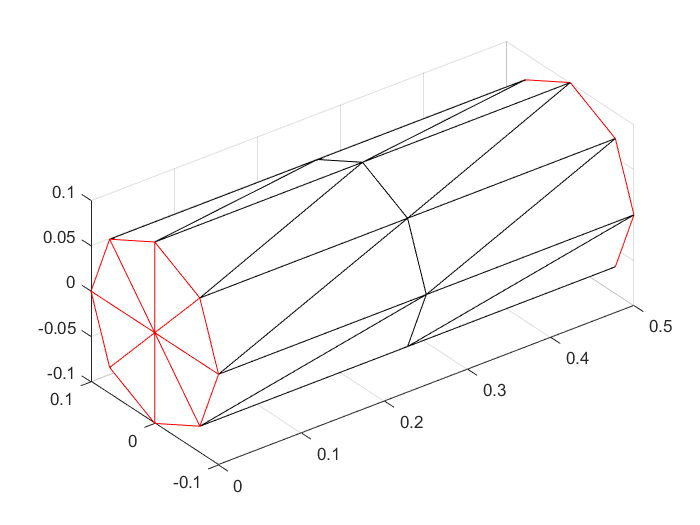

% for iter = 1:19
%---------------------------------------------------------------
% Read/create the mesh and visualise --- the end result here is <node_coords>
% and <tri_nodes>, wherever they were obtained from.
%---------------------------------------------------------------

% Create a plate using basic MATLAB commands:
% if mesh_create_option == 1
%     coords_x            = 0:0.05:3;
%     coords_y            = 0:0.02:0.5;
%     [coords_x,coords_y] = meshgrid(coords_x,coords_y);
%     node_coords         = [coords_x(:) coords_y(:)]; % convert matrices to column vectors
%     node_coords(:,3)    = 0; % z-coord
%     tri_nodes           = delaunay(node_coords(:,1:2));
% end
if mesh_create_option == 1
    a = [1, 0.2, 0.3, 0.4, 0.5, 0.6, 0.7,0.8,0.9,1];
    [node_coords,quad_Elements] = MeshRectanglularPlate(1,1,8,8) ;
    node_coords(:,3) = 0;
    quad_nodes = cell(length(quad_Elements),1);
    for node = 1:length(quad_Elements)
        quad_nodes{node} = [quad_Elements(node,1:4),[0 0 0 0 0 0 0 0]];
    end
    %     [revised_triangles,triangles] = QuadtoTri(quad_Elements);
    [tri_nodes,triangles] = QuadtoTri(quad_Elements, 1, cyl_def);
end

% Import from a Nastran file that was created by FEKO:
if mesh_create_option == 2
    %         [node_coords,tri_nodes] = ImportTriangleMeshNastran('bowtie_1.nas');
    % [node_coords, tri_nodes] = ImportTriangleMeshNastran('C:\Users\19083688\Desktop\Masters\FEKO Models\Meshes\square_plate_hole_20v_regular.nas');
    %     [node_coords, tri_nodes] = ImportTriangleMeshNastran('C:\Users\19083688\Desktop\Masters\FEKO Models\Meshes\cylinder_endcaps_finer.nas');
    [node_coords, tri_nodes] = ImportTriangleMeshNastran('C:\Users\19083688\Desktop\Masters\FEKO Models\RWG Wires\0.2r_zaxis_standard.nas');
    %node_coords(:,3)        = 0.1*rand(size(node_coords,1),1); % just a test
    %     interelem_VsrcZload     = [ 43 108 1 0 50 0]; % [tri- tri+ V_src^real V_src^imag Z_load^real Z_load^imag]
    %     flag_lumped             = true;
    %     interelem_VsrcZload     = [ 43 108 0 0  5e4 0
    %                                 90  80 1 0   0 0
    %                                 82  79 1 0   0 0]; % [tri- tri+ V_src^real V_src^imag Z_load^real Z_load^imag]
end

% Create a custom, junction mesh:
if mesh_create_option == 3
    node_coords = [0 0 0
        1 0 0
        1 1 0
        0 1 0
        0 2 0
        1 2 0];
    tri_nodes = [ 1 2 3
        3 1 4
        4 5 6
        6 3 4];
    %     node_coords = [0   0   0
    %         1   0   0
    %         1   1   0
    %         0   1   0
    %         0.5 0.5 1];
    %     tri_nodes   = [1   2   3
    %         1   3   4
    %         5   1   3];
end

% Mesh a cylinder
if mesh_create_option == 4
    %---------------------------------------------------------------
    %     Standard contour definitions
    %---------------------------------------------------------------
    temp1 = [0.0002 0.0004 0.0008 0.001 0.002 0.003 0.006 0.01 0.03 0.06 0.1 0.13 0.16 0.2 0.23 0.26 0.3 0.33 0.36 0.4];
    radii = {0.0001,0.0004, 0.0008, 0.001, 0.004, 0.008, 0.01, 0.04, 0.08, 0.1, 0.14, 0.18,0.2,0.24,0.28,0.3,0.34,0.38,0.4 };
    %     rho = radii{iter};
    rho = cyl_def.radius;
    vertices = cyl_def.vertices; % Only even number here for endcap mesh (bug with odd numbers)
    Contour = [0 0 0; 0.25 0 0; 0.5 0 0];
    % Mesh a long wire connected to plate
    %      z = repelem(0.5,15)';
    %      y = repelem(0.5,35)';
    %      x = (linspace(-3,3,35));
    %      z = -((x.^18)/600000000) + 0.648; % Brute force equation
    %      z(1) = 0.2;
    %      z(end) = 0.2;
    %      Contour = [-3 0.5 0;  x' y z'; 3 0.5 0];

    %      Contour = [x' y z'];
    %      Contour = RefineMesh([x y z],1);
    
    % Mesh a dipole
    % %      del = (rho*2)/2;
    %      del = 0.04;
    %      del = (rho*1.189)/2;
    % Contour = [0 0 0; 0 0 0.25; 0 0 0.5];
    %     Contour = [0 0 0; 0 0 0.25-del; 0 0 0.25; 0 0 0.25+del;0 0 0.5];
    %     Contour1 = RefineMesh(Contour(1:2,:),3);
    %     Contour2 = RefineMesh(Contour(end-1:end,:),3);
    %     Contour = [Contour1;0 0 0.25;Contour2]; % Constant feed gap width
    %     seg_len(iter) = 1./(length(Contour)-3);
    % Contour = [0 0 0; 0 0 0.25; 0 0 0.5];

    if cyl_def.refinementFactor > 0
        Contour = RefineMesh(Contour,cyl_def.refinementFactor);
    end
    contour_length = length(Contour(:,1));
    %     i = 1;
    %     while i<contour_length % Remove nodes at the feedpoint to get constant gap width
    %         if abs(Contour(i,3) - 0.25)<del && (abs(Contour(i,3) - 0.25) ~= 0.000)
    %             Contour(i,:) = [];
    %         end
    %         contour_length = length(Contour(:,1));
    %         i = i + 1;
    %     end
    numNodes = length(Contour(:,1))-2;
    %---------------------------------------------------------------
    %     Main cylinder meshing routing:
    %---------------------------------------------------------------
    [node_coords,quad_nodes, elements] = CylMesh(Contour,vertices,rho, cyl_def);
    
    %---------------------------------------------------------------
    %     Mesh cylinder connected to external geometry
    %---------------------------------------------------------------
    if cyl_def.firstNode == "conn" || cyl_def.lastNode == "conn"
        if cyl_def.coupling % Connected to geometry and another cylinder with y-offset

            cyl_def.plate_polygon_nodes = [];
            cyl_def.plate_polygon_nodes_end = [];

            elements_temp = elements;
            node_coords_temp = node_coords ;
            node_coords_temp(:,2) = node_coords_temp(:,2) - 1; % Shift y-axis by 1

            % Connect original cylinder to plate
            [node_coords, elements, ~, cyl_def, last_element_val, ~] = ConnectToPlate_v2(cyl_def, node_coords,elements, vertices);
            elements(1:vertices,1:2) = elements(1:vertices,1:2) + last_element_val; % Since the plate will be offset by another cylinder's nodes
            elements(end-vertices+1:end,1:2) = elements(end-vertices+1:end,1:2) + last_element_val;

            % Connect second cylinder to plate
            elements_temp = elements_temp + last_element_val;
            %             cyl_def.cylIndices = [1,last_element_val*2];
            [node_coords_temp, elements_temp, plate_tri_nodes, cyl_def, last_element_val, plate_node_coords] = ConnectToPlate_v2(cyl_def, node_coords_temp,elements_temp, vertices);
            %             cyl_def.cylIndices
            % Add together first & second cylinder's coordinates and elements
            node_coords = [node_coords;node_coords_temp; plate_node_coords];
            elements = [elements;elements_temp];

            numNodes = (length(Contour(:,1))-2)*2;

        else
            [node_coords, elements, plate_tri_nodes, cyl_def, last_element_val] = ConnectToPlate_v2(cyl_def, node_coords,elements, vertices);
        end

        [tri_nodes,triangles] = QuadtoTri(elements, vertices,cyl_def);
        tri_nodes = [tri_nodes;(plate_tri_nodes+last_element_val)];

    else % No connection geometry
        cyl_def.plate_polygon_nodes = [];
        cyl_def.plate_polygon_nodes_end = [];
        cyl_def.num_plate_nodes = 0; % Number of nodes to exclude from MBF

        if cyl_def.coupling
            node_coords_temp = node_coords ;
            node_coords_temp(:,2) = node_coords_temp(:,2) - 0.5; % Shift y-axis by 1
            node_coords = [node_coords;node_coords_temp];
            elements_temp = elements;
            elements_temp = elements_temp + length(node_coords);
            elements = [elements;elements_temp];
            numNodes = (length(Contour(:,1))-2)*2;
        end

        [tri_nodes,triangles] = QuadtoTri(elements, vertices,cyl_def);
    end
    %---------------------------------------------------------------
    %     Lumped element excitation
    %---------------------------------------------------------------
    if flag_lumped
        % Find the triangles around a node to excite or load
        % arg: [excitation_location, tri_nodes,node_coords, vertices,coordinate_to_examine (x-1/y-2/z-3),[]]
        if cyl_def.coupling
            [tri_indices] = FindTrianglesAroundNode(0, tri_nodes,node_coords,vertices, 1,[]);
        else
            if solver == 2 || solver == 1
                [tri_indices] = FindTrianglesAroundNode(0.25, tri_nodes,node_coords,vertices, 3,[]);
            else
                [tri_indices] = FindTrianglesAroundNode(0.25, elements,node_coords,vertices, 3,[]);
            end
        end

        if cyl_def.coupling
            tri_indices = tri_indices(1:round(end/2),:); % Because the second cylinder is also selected here, which we do not want.

            % This here shabang converts them connection nodes into those
            % appropriate triangle pairs we so desire
            load_tris = ismember(tri_nodes,(cyl_def.plate_polygon_nodes(end-vertices+1:end)+cyl_def.last_element_val));
            [tri_indices_load, ~] = find(sum(load_tris,2) >=2);
            tri_indices_load(1:vertices,2) = tri_indices_load(vertices+1:end);
            tri_indices_load(vertices+1:end,:) = [];

            load_tris2 = ismember(tri_nodes,(cyl_def.plate_polygon_nodes_end(end-vertices+1:end)+cyl_def.last_element_val));
            [tri_indices_load2, ~] = find(sum(load_tris2,2) >=2);
            tri_indices_load2(1:vertices,2) = tri_indices_load2(vertices+1:end);
            tri_indices_load2(vertices+1:end,:) = [];

        end

        %          [tri_indices_load] = 1:2:vertices*2; % Triangles on the cylinder at the junction
        % %          [tri_indices_load] = cyl_def.plate_polygon_nodes(end-vertices+1:end)+cyl_def.last_element_val;
        %          [t,l] = ismember(tri_nodes,tri_nodes(tri_indices_load));
        %           temp = find(sum(t~=0,2) > 1); % Triangles on the cylinder and the plate at the junction
        %          % Now align them
        %           for i = 1:vertices
        %               A = nonzeros(l(tri_indices_load(i),:));
        %               rows(i,1:2) = find(sum(ismember(l,A),2)>=2);
        %           end
        %
        %          tri_indices_load = rows;
        if solver == 2
            tri_indices = tri_indices*2; % For first order spec.
            tri_indices_load = tri_indices_load*2;
            tri_indices_load2 = tri_indices_load2*2;
        end
        ELength = 2*rho*sind((360/vertices)/2);

        interelem_VsrcZload = [tri_indices, repmat([1 0], [vertices,1]), repmat([0 0], [vertices,1])]; % [tri- tri+ V_src^real V_src^imag Z_load^real Z_load^imag]:
        if cyl_def.coupling
            interelem_VsrcZload = [interelem_VsrcZload;[tri_indices_load, repmat([0 0], [vertices,1]), repmat([50 0], [vertices,1])]]; % This puts a 50 Ohm load on the node connecting the cylinder to the plate
            interelem_VsrcZload = [interelem_VsrcZload;[tri_indices_load2, repmat([0 0], [vertices,1]), repmat([50 0], [vertices,1])]]; % This puts a 50 Ohm load on the node connecting the cylinder to the plate
        end
    end

    if show_output
        figure;
        trimesh(tri_nodes,node_coords(:,1),node_coords(:,2),node_coords(:,3),"EdgeColor", "Black") ;
        hold on 
        trimesh(tri_nodes(end-(vertices*2)+1:end,:),node_coords(:,1),node_coords(:,2),node_coords(:,3), "EdgeColor", "Red") ;
        axis equal
        %  PlotMesh(node_coords,elements, tri_nodes, mod(solver,3));
    end

end


% Mesh a sphere
if mesh_create_option == 5
    %     radius = 0.1;
    radius = linspace(0.04, 1.2, 60);
    %     radius = [0.05,0.1,0.15, 0.2,0.3,0.38, 0.4,0.48,0.52, 0.6,0.65,0.7, 0.8,0.85,0.9, 0.95, 1,1.05,1.1, 1.2];
    grid     [node_coords, quad_elems] = MeshCube(12,0.5);
    quad_nodes = cell(length(quad_elems),1);
    for node = 1:length(quad_elems)
        quad_nodes{node} = [quad_elems(node,1:4),[0 0 0 0 0 0 0 0]];
    end
    if solver ~= 3
        [tri_nodes,triangles] = QuadtoTri(quad_elems, 1, cyl_def);
    end
%              patch('Faces',tri_nodes,'Vertices',node_coords);
end

### Mesh pre-processing & Visualisation

The end result here is <mesh_data> which contains all the necessary derived information from the mesh, required for assigning dofs.

% Create the mesh data, which includes edge definitions and connectivity:
if solver == 3
    % NB: EdgeCalcQuad has functionality for specific directions tailored to cylinders, for help in constructing the MBF
    % If it is desired to run this on generic meshes, comment that code
    vertices = 1;
    [quad_blah,N,basis_supports_quad, quad_Edges,quad_dofs_to_edges] = EdgeCalcQuad(quad_nodes,vertices);

    obs_basis_select = {1:N};
    src_basis_select      = {1:N};
    [common_basis_functions, num_obs, num_src] = common_basis(obs_basis_select,src_basis_select);
    quad_dof_idx = (1:N)';
    [new_quads,new_quad_points, new_quad_N, quad_observer_map, quad_source_map] = QuadBasisFunctionSelect(quad_blah ,common_basis_functions,basis_supports_quad,node_coords);

else

    if solver == 2
        tri_nodes = repelem(tri_nodes,2,1);
    end
    [mesh_data] = CreateMeshData(node_coords,tri_nodes);
    %     clear node_coords tri_nodes quad_blah quad_nodes;

    % Visualize the processed mesh data:
    %    patch('Faces',tri_nodes,'Vertices',node_coords,'EdgeColor','blue','FaceColor','none');  % ,'LineWidth',2
    %
    %     for ii = 1:vertices
    %         for jj = 1:2
    %         n1 =  tri_nodes(tri_indices_load2(ii,jj),1);
    %         n2 =  tri_nodes(tri_indices_load2(ii,jj),2);
    %         n3 =  tri_nodes(tri_indices_load2(ii,jj),3);
    %         tricentroid = (1/3) * (node_coords(n1,:) + node_coords(n2,:) + node_coords(n3,:));
    %         text(tricentroid(1),tricentroid(2),tricentroid(3),num2str(tri_indices_load2(ii,jj)),'HorizontalAlignment','center','Color','b'); % ['t',num2str(ii)]
    %
    %         end
    %     end

    %     PlotTriangleMeshRaw(node_coords,tri_nodes,TextOn)
    %         PlotTriangleMeshProcessed(mesh_data,TextOn);

    %---------------------------------------------------------------
    % Make uniform mesh refinement.
    %---------------------------------------------------------------

    % TODO: This does not work for first order yet.
    if flag_mesh_refine_uniform==true
        [node_coords,tri_nodes] = MeshRefineUniformSplit(mesh_data,h_split_num);
        [mesh_data] = CreateMeshData(node_coords,tri_nodes);
        clear node_coords tri_nodes;
        PlotTriangleMeshProcessed(mesh_data,TextOn);
    end

    %---------------------------------------------------------------
    % Define all the RWG basis functions of the mesh.
    %---------------------------------------------------------------

    % Assign the dofs and define each associated basis function:
    [dof_data,num_dofs] = CreateBasisFunctions_New(mesh_data, solver-1); % 1 for first order
    %     [dof_data,num_dofs] = CreateBasisFunctions(mesh_data); % 1 for first order
    % %             PlotTriangleMeshDofs(mesh_data,dof_data,TextOn, solver -1);
    N = num_dofs;
    %---------------------------------------------------------------
    % Reduce the matrix if required; set up the excitation vector, system
    % matrix, and solve.
    %---------------------------------------------------------------

    % Build the sparse contributions to the full system due to lumped elements.
    % The contributions can then be suitably reduced according to the selected
    % sources and observers. The reason for not filling this after reduction,
    % is because the lumped elements are specified in terms of the original
    % mesh. Therefore the other option would be to recreate the lumped element
    % specs in terms of the reduced mesh first and then work with that, but
    % such an approach is more complicated, since it would effectively require
    % that the full <dof_data> be reduced, since that is what is needed to
    % assemple the lumped contributions (they are defined in terms of triangle
    % numbers, not just i.t.o. dof numbers and triangle coords).
    if flag_lumped
        if solver == 2
            [Zlump_rowcolval, Vlump_rowcolval] = CalcZmatVvecLumpedFO(dof_data, num_dofs, mesh_data, interelem_VsrcZload);
            %              [Zlump_rowcolval_load, Vlump_rowcolval_load] = CalcZmatVvecLumpedFO(dof_data, num_dofs, mesh_data, interelem_VsrcZload_load);
        else
            [Zlump_rowcolval, Vlump_rowcolval] = CalcZmatVvecLumped(dof_data, num_dofs, mesh_data, interelem_VsrcZload);
        end

    end

    % Code to reduce the number of dofs and also to selectively calculate matrix entries/blocks.
    % Define observers and sources required:
    % (V 3.1 allows for basis function selection, the result yields a N_new by
    % N_new matrix, every basis function is both source and observer.)
    obs_basis_select = 1:num_dofs;
    src_basis_select = 1:num_dofs;

    % Find the union of the observer and source list and append flags + record
    % total observers and sources to calculate:
    [common_basis_functions, num_obs, num_src, global_to_redu_dofs] = CommonBasis(obs_basis_select,src_basis_select,num_dofs,true);

    % Set up reduced set up dofs and mesh nodes, only relevant to the requested
    % common basis functions:
    [reduced_tri_dofs,reduced_node_coords, reduced_num_dofs, ...
        observer_map, source_map] = BasisFunctionSelect(dof_data.tri_dofs,common_basis_functions,dof_data.basis_supports,mesh_data.node_coords);

    % 2020/04/06 Edit
    % Merge rows for more compact data struct
    if solver == 2
        %         reduced_tri_dofs_RWG = reduced_tri_dofs;
        for ii = 2:2:length(reduced_tri_dofs)%-(cyl_def.num_plate_nodes*2 - (2*(cyl_def.firstNode == "conn"))) % Make everything first order except those triangles of the plate
            reduced_tri_dofs(ii-1,10:15) = reduced_tri_dofs(ii,4:9);
        end
        reduced_tri_dofs = reduced_tri_dofs(1:2:end,:);% Delete extra rows
    else
        %         reduced_tri_dofs(:,10:15) = 0;
    end

end

<observer_map> and <source_map> should be constructed in CommonBasis, rather than in BasisFunctionSelect


### MoM Calculations

Mode =0

Mode = 0


if solver == 3
    tic
    [Z_mat] = qmom(new_quad_points, new_quads, new_quad_N, FREQUENCY,int32(quad_observer_map),int32(quad_source_map), num_obs, num_src, MODE);
    toc
    V_vec     = zeros(new_quad_N,1);
    if flag_lumped
        [Zlump_reduced, Vlump_reduced] = FinalZmatVvecLumped(Zlump_rowcolval, Vlump_rowcolval, global_to_redu_dofs, num_obs, num_src, observer_map, source_map);
        Z_mat = Z_mat + Zlump_reduced;
        V_vec = V_vec + Vlump_reduced;
    else
        V_vec = qfillPlane(new_quad_points, new_quads, new_quad_N, FREQUENCY,int32(quad_observer_map), num_obs, MODE, theta_inc, phi_inc, eta_pol);
    end
else

    tic
    if solver == 1
        [Z_mat] = mom(reduced_node_coords, reduced_tri_dofs, reduced_num_dofs, FREQUENCY,int32(observer_map),int32(source_map), num_obs, num_src, MODE);
    else
        [Z_mat] = FOmom(reduced_node_coords, reduced_tri_dofs, reduced_num_dofs, FREQUENCY,int32(observer_map),int32(source_map), num_obs, num_src, MODE, solver-1);
    end
    toc
    V_vec     = zeros(num_dofs,1);
    if flag_planewave
        if solver ~= 1
            V_vec  = FOfillPlane(reduced_node_coords, reduced_tri_dofs, reduced_num_dofs, FREQUENCY,int32(observer_map), num_obs, MODE,solver-1, theta_inc, phi_inc, eta_pol);
        else
            %              V_vec  = FOfillPlane(reduced_node_coords, reduced_tri_dofs, reduced_num_dofs, FREQUENCY,int32(observer_map), num_obs, MODE,solver-1, theta_inc, phi_inc, eta_pol);
            % MATLAB version:
            V_vec = CalcExciteVecPlaneWave(reduced_tri_dofs,reduced_node_coords, observer_map, k0, E_scalfac, theta_inc, phi_inc, eta_pol);
        end
    end

    % Add lumped circuit element contributions to the reduced Z and V, by
    % obtaining the contributions in sparse format and then adding to the
    % system:
    if flag_lumped
        [Zlump_reduced, Vlump_reduced] = FinalZmatVvecLumped(Zlump_rowcolval, Vlump_rowcolval, global_to_redu_dofs, num_obs, num_src, observer_map, source_map);
        Z_mat = Z_mat + Zlump_reduced;
        V_vec = V_vec + Vlump_reduced;

    end
end


3 3: 128
3 3: 0
4 4: 528
6 6: 592
7 7: 7056
7 RAR: 336

If it were done when 'tis done, then 'twere well It were done quickly


Elapsed time is 0.895315 seconds.


MODE = 0

If it were done when 'tis done, then 'twere well It were done quickly


### MBF Calculation

curr =     1.0000    2.0000    1.0000
    2.0000    1.0000    2.0000
    2.0000    2.4142    2.0000
    2.4142    2.0000    2.4142
    2.4142    2.0000    2.4142
    2.0000    2.4142    2.0000
    2.0000    1.0000    2.0000
    1.0000    2.0000    1.0000
    1.0000         0    1.0000
         0    1.0000         0


curr_dir =     1.3333   -0.0000    0.0000
    1.6667   -0.0000    0.0000
    2.1381   -0.0000    0.0000
    2.2761    0.0000   -0.0000
    2.2761   -0.0000   -0.0000
    2.1381   -0.0000   -0.0000
    1.6667   -0.0000   -0.0000
    1.3333   -0.0000   -0.0000
    0.6667         0         0
    0.3333    0.0000   -0.0000


path = "C:\Users\jduplessis\Desktop\Journal_Article_Figs\axial_0.1endCap_endCap8_analytical.png"

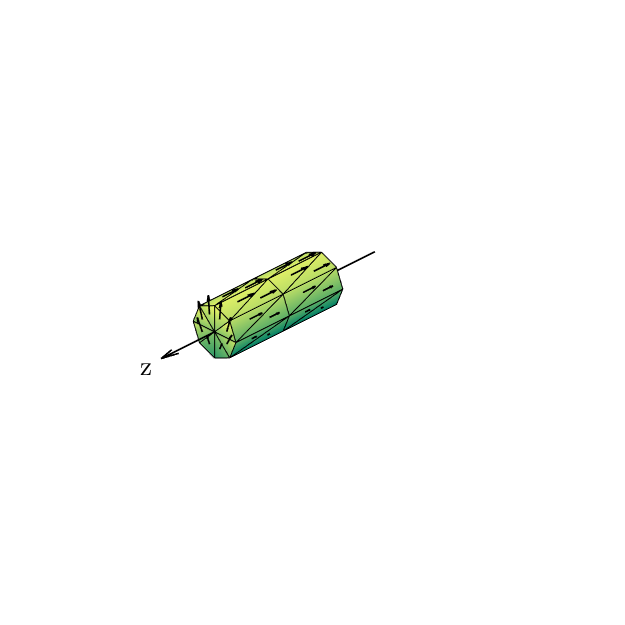


numMBF = 3 ;
if solver == 3
    if MBF == 1 % Quadrilateral MBF's

        U_Mat = [];
        [U_Mat] = SelectDOFMBF(basis_supports_quad, vertices,numNodes,numMBF);
        %         U_Mat = zeros(length(basis_supports_quad),1);
        [U_Mat] = SelectDOFMBF_2(basis_supports_quad, vertices, U_Mat,numNodes,numMBF);
        %                 PlotTriangleMeshDofsMBFQuad(node_coords,quad_blah,TextOn, U_Mat, quad_Edges, quad_dofs_to_edges);
        U_Mat(:,~any(U_Mat,1)) = []; % Remove zero columns
    end
else
    if MBF == 1 % FO MBF's
        U_Mat = zeros(length(V_vec));
        if cyl_def.MBF == "axial"
            [U_Mat, DOF_mat1, DOF_mat2, DOF_mat3] = MBF_Axial_endcap(mesh_data, dof_data, vertices, numMBF, numNodes, reduced_tri_dofs,cyl_def);
        elseif cyl_def.MBF == "both"
            [U_Mat, DOF_mat1, DOF_mat2, DOF_mat3] = MBF_Axial_endcap(mesh_data, dof_data, vertices, numMBF, numNodes, reduced_tri_dofs,cyl_def);
            [U_Mat, DOF_mat, theta1, theta2] = MBF_Circ_endcap(mesh_data, dof_data, vertices ,numMBF, numNodes, reduced_tri_dofs, cyl_def, U_Mat);
        else
            [U_Mat, DOF_mat, theta1, theta2] = MBF_Circ_endcap(mesh_data, dof_data, vertices ,numMBF, numNodes, reduced_tri_dofs, cyl_def, U_Mat);
        end

        if cyl_def.firstNode == "conn" % This ensures no MBF's defined on external geometry
            col = length(U_Mat(1,:));
            for i = length(reduced_tri_dofs)-cyl_def.num_plate_nodes + 2:length(reduced_tri_dofs)
                for j = 1:3
                    if reduced_tri_dofs(i,j+6) ~= -1 && nnz(U_Mat(reduced_tri_dofs(i,j+6),:)) == 0 %&& ~ismember(reduced_tri_dofs(i,j+6),DOF_mat(:,11))
                        col = col + 1;
                        U_Mat(reduced_tri_dofs(i,j+6),col) = 1; % Make all RWG components simply 1 in U_Mat
                    end
                end
            end
        end

        
        U_Mat(:,~any(U_Mat,1)) = []; % Remove zero columns
    %---------------------------------------------------------------
    %    Some debugging visualisation stuff:
    %---------------------------------------------------------------
    %         PlotTriangleMeshDofsMBF(mesh_data,dof_data,TextOn, U_Mat,9);
%                 [x_axis, current_norm, current_MBF] = plotNodeCurrent(I_vec,I_vec_norm,DOF_mat1,DOF_mat2,DOF_mat3,DOF_mat, numNodes,meshEndcapFlag);
        %         [U_Mat] = SelectDOFMBF_FO_New_2( vertices, numNodes,numMBF,reduced_tri_dofs, U_Mat, meshEndcapFlag);
        %         PlotMesh(mesh_data.node_coords,elements, triangles, mod(solver,3));
        %         hold on
%                 PlotMBFMeshDofs(mesh_data,dof_data,TextOn, DOF_mat(:,9));
        %                 PlotTriangleMeshDofsMBF(mesh_data,dof_data,TextOn, U_Mat,73);
        %         hold off
    end
end

    %---------------------------------------------------------------
    %    Solve the linear equations
    %---------------------------------------------------------------
if MBF == 0
    I_vec = Z_mat\V_vec;
else

    Z_mat_redu = U_Mat.'*Z_mat*U_Mat;
    V_vec_redu = U_Mat.'*V_vec;
    Alpha_Vec_Redu = Z_mat_redu\V_vec_redu;
    New_N = size(Alpha_Vec_Redu,1);
    I_vec = U_Mat*Alpha_Vec_Redu;

    iden = eye(size(U_Mat,1));
    Z_mat_redu_iden = eye(New_N);
    V_vec_redu_iden = ones(New_N,1);
    Alpha_Vec_Redu_iden = Z_mat_redu_iden\V_vec_redu_iden;
    I_vec_iden = U_Mat*Alpha_Vec_Redu_iden;
end
I_vec_norm = Z_mat\V_vec;


    %---------------------------------------------------------------
    %    Post-processing
    %---------------------------------------------------------------
% Calculate and plot the surface current distribution, and current direction.
% Calculate the surface current density at the three vertices of all mesh triangle:
if solver == 3 && show_output % Quadrilateral
    num_quad = size(new_quads,1);
    [quads_vertices_currents] = CalcElementsCurrentsQuad(I_vec, new_quads, quad_dof_idx, num_quad, node_coords);

    % Calculate centroid and vertex current magnitudes:
    quad_currents_cent = zeros(num_quad,1);
    quad_currents_dir = zeros(num_quad,3);
    quad_currents_vert = zeros(num_quad,4);
    quad_currents_real = zeros(num_quad,1);
    quad_currents_imag = zeros(num_quad,1);
    for ii = 1:num_quad
        J_centroid              = (1/4)*[1 1 1 1]*squeeze(quads_vertices_currents(ii,1:4,1:3)); % Add each component at all 3 vertices and average
        for kk = 1:4 % Cycle of 4 vertices of quad
            quad_currents_dir(ii,1) =  quad_currents_dir(ii,1) + quads_vertices_currents(ii,kk,1);
            quad_currents_dir(ii,2) =  quad_currents_dir(ii,2) + quads_vertices_currents(ii,kk,2);
            quad_currents_dir(ii,3) =  quad_currents_dir(ii,3) + quads_vertices_currents(ii,kk,3);
        end
        quad_currents_cent(ii,1) = sqrt(abs(J_centroid*J_centroid'));
        quad_currents_real(ii,1) = norm(real(J_centroid));
        quad_currents_imag(ii,1) = norm(imag(J_centroid));
        for jj = 1:4
            J_vertex                 = squeeze(quads_vertices_currents(ii,jj,1:3)).'; % non-conjugate transpose to make this a row vector
            quad_currents_vert(ii,jj) = sqrt(abs(J_vertex*J_vertex')); % Magnitude
        end
    end
    quad_currents_dir_real = real(quad_currents_dir);
    quad_currents_dir_imag = imag(quad_currents_dir);
elseif show_output % RWG and FO

    num_tri = size(reduced_tri_dofs,1);
    tri_dof_idx = (1:N)';

    [triangles_vertices_currents] = CalcElementsCurrentsFO(I_vec, reduced_tri_dofs, tri_dof_idx, num_tri, mesh_data.node_coords, solver -1, mesh_data);
    [triangles_vertices_currents_iden] = CalcElementsCurrentsFO(I_vec_iden, reduced_tri_dofs, tri_dof_idx, num_tri, mesh_data.node_coords, solver -1, mesh_data);
    [triangles_vertices_currents_norm] = CalcElementsCurrentsFO(I_vec_norm, reduced_tri_dofs, tri_dof_idx, num_tri, mesh_data.node_coords, solver -1, mesh_data);

    % Calculate centroid and vertex current magnitudes:
    tri_currents_cent = zeros(num_tri,1);
    tri_currents_cent_iden = zeros(num_tri,1);
    tri_currents_cent_norm = zeros(num_tri,1);
    tri_currents_dir = zeros(num_tri,3);
    tri_currents_dir_iden = zeros(num_tri,3);
    tri_currents_dir_norm = zeros(num_tri,3);
    tri_currents_vert = zeros(num_tri,3);
    tri_currents_vert_norm = zeros(num_tri,3);
    tri_currents_vert_iden = zeros(num_tri,3);
    tri_currents_real = zeros(num_tri,1);
    tri_currents_imag = zeros(num_tri,1);
    for ii = 1:num_tri
        J_centroid              = (1/3)*[1 1 1]*squeeze(triangles_vertices_currents(ii,1:3,1:3)); % Add each component at all 3 vertices and average
        J_centroid_iden         = (1/3)*[1 1 1]*squeeze(triangles_vertices_currents_iden(ii,1:3,1:3));
        J_centroid_norm         = (1/3)*[1 1 1]*squeeze(triangles_vertices_currents_norm(ii,1:3,1:3)); % Add each component at all 3 vertices and average
        tri_currents_cent(ii,1) = sqrt(abs(J_centroid*J_centroid'));
        tri_currents_cent_iden(ii,1) = sqrt(abs(J_centroid_iden*J_centroid_iden'));
        tri_currents_cent_norm(ii,1) = sqrt(abs(J_centroid_norm*J_centroid_norm'));

        tri_currents_real(ii,1) = norm(real(J_centroid));
        tri_currents_imag(ii,1) = norm(imag(J_centroid));

        tri_currents_dir(ii,:) = real(J_centroid);
        tri_currents_dir_iden(ii,:) = real(J_centroid_iden);
        tri_currents_dir_norm(ii,:) = real(J_centroid_norm);

        for jj = 1:3
            J_vertex                 = squeeze(triangles_vertices_currents(ii,jj,1:3)).'; % non-conjugate transpose to make this a row vector
            J_vertex_norm            = squeeze(triangles_vertices_currents_norm(ii,jj,1:3)).'; % non-conjugate transpose to make this a row vector
            J_vertex_iden           = squeeze(triangles_vertices_currents_iden(ii,jj,1:3)).';
            tri_currents_vert(ii,jj) = sqrt(abs(J_vertex*J_vertex')); % Magnitude
            tri_currents_vert_norm(ii,jj) = sqrt(abs(J_vertex_norm*J_vertex_norm')); % Magnitude
            tri_currents_vert_iden(ii,jj) = sqrt(abs(J_vertex_iden*J_vertex_iden')); % Magnitude
            %             tri_currents_vert(ii,jj) = imag(J_vertex(jj));
        end
    end
end

% Calculate diff:
% diff_currents = tri_currents_vert - tri_currents_vert_norm;
% diff_currents_dir = tri_currents_dir - tri_currents_dir_norm;

% Visualize the current:
if solver == 3 && show_output
    PlotCurrent3DQuad(1,false,quad_blah,node_coords,quad_currents_vert);
    quiverObject = PlotCurrentDir3D(0,quad_blah,node_coords,quad_currents_dir_real,quad_currents_dir);
    
    Format3DGraph(quiverObject, cyl_def)
elseif solver == 2 && show_output
    if quantityToPlot == "iden"
        curr = tri_currents_vert_iden
        curr_dir = tri_currents_dir_iden
    elseif quantityToPlot == "norm"
       curr = tri_currents_vert_norm
       curr_dir = tri_currents_dir_norm
    else
       curr = tri_currents_vert 
       curr_dir = tri_currents_dir
    end
    % Plot current magnitude:
    % [tri_currents_vert_iden, tri_currents_real, tri_currents_imag,tri_currents_vert, tri_currents_cent, tri_currents_vert_norm, tri_currents_cent_norm, diff_currents]
     
    PlotCurrent3D(1,showEdges,mesh_data.tri_nodes(1:2:end,:), mesh_data.node_coords,curr);
    colormap summer;
    %     Format3DGraph()
    % Plot current direction (quiver):
    quiverObject = PlotCurrentDir3D(1,mesh_data.tri_nodes(1:2:end,:),mesh_data.node_coords,curr_dir);
    Format3DGraph(quiverObject, cyl_def, quantityToPlot) % Formatting for Journal article
%        [x_axis, current_norm, current_] = plotNodeCurrent(I_vec,I_vec_norm,DOF_mat1,DOF_mat2,DOF_mat3,DOF_mat, numNodes,cyl_def);
    % Plot the DOF numbers on the mesh (debugging purposes)
%     PlotMBFMeshDofs(mesh_data,dof_data,TextOn, DOF_mat3(:,end));
%     PlotTriangleMeshDofsMBF(mesh_data,dof_data,TextOn, U_Mat,1);
     
elseif solver == 1 && show_output
    PlotCurrent3D(0,false,mesh_data.tri_nodes, mesh_data.node_coords,tri_currents_cent);
    PlotCurrent3D(1,false,mesh_data.tri_nodes,mesh_data.node_coords,tri_currents_vert);
    PlotCurrentDir3D(1,mesh_data.tri_nodes,mesh_data.node_coords,tri_currents_dir);
end


%---------------------------------------------------------------
% Custom impedance calculation for the 'bowtie_1.nas' mesh, when excited at the neck: edge nodes 24 and 28; dof number 49.
%---------------------------------------------------------------
% solver = solver -1;
% if flag_lumped
%     if num_dofs > 48
%         edgevectemp = mesh_data.node_coords(28,:) - mesh_data.node_coords(24,:);
%         ELength     = sqrt(edgevectemp*edgevectemp');
%         Z_11        = 1/(ELength*I_vec(49,1))
% %         disp('General source impedance calculation must still be implemented');
%     end
% end

if flag_lumped % Current, impedance, etc calculation for lumped load
    Z_11_Z_mat_norm = 0;
    Z_load = 0;
    edge_select = 1-solver;

    for i = 1:vertices
        edge_select = edge_select + solver;
        edge        = intersect(mesh_data.edges(mesh_data.tri_edges(tri_indices(i,1),:),:),mesh_data.edges(mesh_data.tri_edges(tri_indices(i,2),:),:), 'rows');
        edgevectemp = reduced_node_coords(edge(1),:) - reduced_node_coords(edge(2),:);
        ELength     = sqrt(edgevectemp*edgevectemp');
    end

    %     voltage         = sum(Vlump_rowcolval(:,3));
    %     current         = sum(I_vec(Vlump_rowcolval(:,1),1));
    %     current_norm    = sum(I_vec_norm(Vlump_rowcolval(:,1),1));
    % %     current         = current/(vertices*ELength); % Average value of current, normalised by numVertices*ELength.
    % %     current_norm    = current_norm/(vertices*ELength); % Average value of current, normalised by numVertices*ELength.
    %     voltage         = voltage/(vertices*ELength); % Sanity check
    %
    %     Z_11            = 1/(ELength*current) % Ohm's law, Voltage=1V.
    %     Z_11_norm       = 1/(ELength*current_norm)

    %     abs(Z_11)
    %     abs(Z_11_norm)
    voltage         = sum(Zlump_rowcolval(1:40,3));
    current         = sum(I_vec(Zlump_rowcolval(1:40,1),1));
    current_norm    = sum(I_vec_norm(Zlump_rowcolval(1:40,1),1));
    voltage         = voltage/(vertices*ELength); % Sanity check
    Z_11            = 1/(ELength*current) % Ohm's law, Voltage=1V.
    Z_11_norm       = 1/(ELength*current_norm)

    %     G_B(iter) = 1/Z_11  % Input Conductance + Susceptance
    %     G_B_norm(iter) = 1/Z_11_norm;


    %     Z_11 = Z_11 * (1/(2*pi*rho)); % Effective edge length normalisation
    %     Z_11_Z_mat = sum(diag(Z_mat(DOF_mat1(:,9),DOF_mat1(:,9))));
    %             disp('General source impedance calculation must still be implemented');
    % end
end

%---------------------------------------------------------------
% Calculate and plot the farfield.
%---------------------------------------------------------------

% The output of the farfield routine has this row format:
% THETA     PHI     magn{Etheta} phase{Etheta} magn{Ephi} phase{Ephi}
%   1        2            3           4            5          6
plane               = 'XZ'; % set the observation plane: 'XY' or 'XZ' or 'YZ'
delta_angle_degrees = 2;    % degree increment for observation directions
if solver == 3
    [farfield_XY] = qfarfield(new_quad_points, new_quads, new_quad_N, FREQUENCY, I_vec, delta_angle_degrees, plane);
    %     [farfield_XY_norm] = qfarfield(new_quad_points, new_quads, new_quad_N, FREQUENCY, I_vec_norm, delta_angle_degrees, plane);
elseif solver == 2
    [farfield_XY] = FOfarfield(reduced_node_coords, reduced_tri_dofs, reduced_num_dofs, FREQUENCY, I_vec, delta_angle_degrees, plane, solver-1);
    [farfield_XY_norm] = FOfarfield(reduced_node_coords, reduced_tri_dofs, reduced_num_dofs, FREQUENCY, I_vec_norm, delta_angle_degrees, plane, solver-1);
    % [farfield_XY_norm] = FOfarfield(reduced_node_coords_RWG, reduced_tri_dofs_RWG, reduced_num_dofs_RWG, FREQUENCY, I_vec_norm, delta_angle_degrees, plane, 0);
else
    [farfield_XY] = farfield(reduced_node_coords, reduced_tri_dofs, reduced_num_dofs, FREQUENCY, I_vec, delta_angle_degrees, plane);
    %     [farfield_XY] = farfield(reduced_node_coords, reduced_tri_dofs, reduced_num_dofs, FREQUENCY, I_vec_rwg, delta_angle_degrees, plane);
end


If it were done when 'tis done, then 'twere well It were done quickly



If it were done when 'tis done, then 'twere well It were done quickly


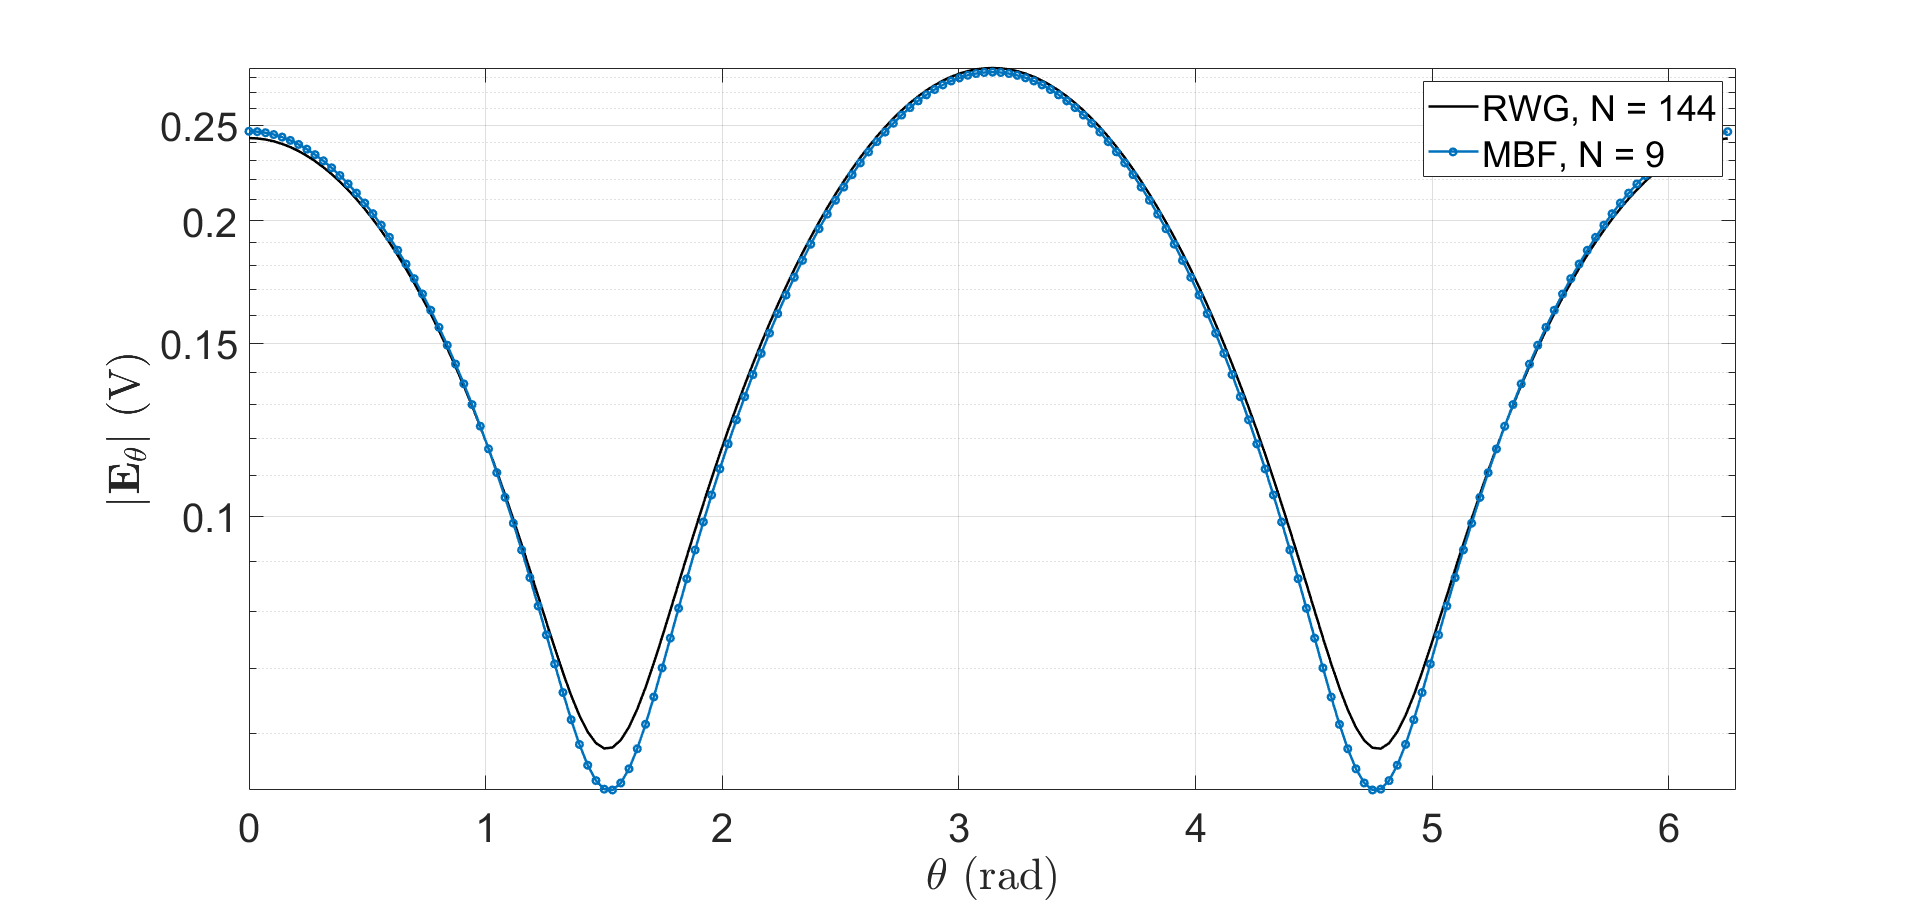

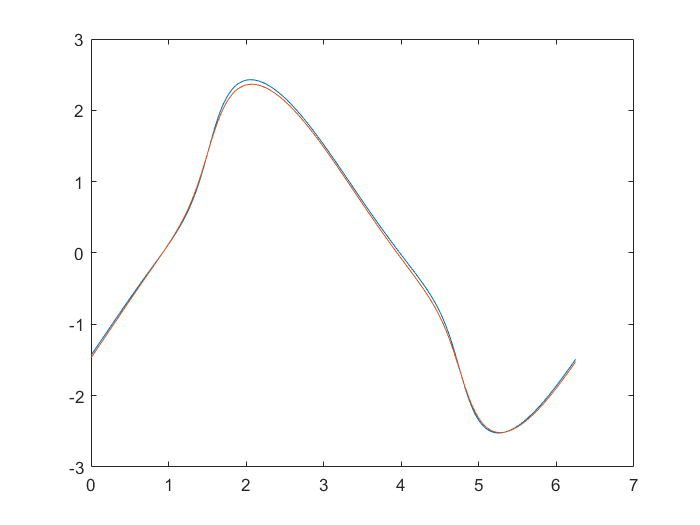


% disp('<farfield> routine still needs some generalisation work');
if show_output && MBF == 1
    %     figure;
    formatFarfield(farfield_XY,farfield_XY_norm,New_N, N,plane);
    %     MBF_plot = semilogy(farfield_XY(:,1),sqrt(farfield_XY(:,3).^2 + farfield_XY(:,5).^2),'LineWidth',1.5);
    %     hold on
    figure
    plot(farfield_XY(:,1),farfield_XY(:,4))
    hold on
    plot(farfield_XY_norm(:,1),farfield_XY_norm(:,4))
end


% [E_field_FEKO] = feko_farfield_extract('C:\Users\19083688\Desktop\MoM Codes\V_3.6_feat_speed\Jacques\FEKO\Hollow_Cylinder_0.1.txt');

% semilogy
% plot(E_field_FEKO(:,1)*(pi/180),sqrt(E_field_FEKO(:,3).^2 + E_field_FEKO(:,5).^2), '+-');

% if MBF == 1 && show_output
%     title('|$E_{\phi}$|')
%     REF_plot = semilogy(farfield_XY_norm(:,1),sqrt(farfield_XY_norm(:,3).^2 + farfield_XY_norm(:,5).^2),'LineWidth',1.5);
%     %     legend("Matlab, N(MBF) = " + New_N,  "FEKO", "Matlab, N = " + N)
%     legend("Matlab, N(MBF) = " + New_N,  "Matlab, N = " + N)
% elseif show_output
%     title('|$E_{\phi}$|')
%      semilogy(E_field_FEKO(:,1)*(pi/180),sqrt(E_field_FEKO(:,3).^2 + E_field_FEKO(:,5).^2), '+-');
%     legend("Matlab, N = " + N, "FEKO")
% end


% xlabel('\phi')
% ylabel('|E_{\phi}|');
if solver == 2
    s1 = "MBF"
elseif solver == 1
    s1 = "RWG"
else
    s1 = "Quad"
end

s1 = "MBF"

farfield_XZ_all(:,iter) = sqrt(farfield_XY(:,3).^2 + farfield_XY(:,5).^2);

Unrecognized function or variable 'iter'.


% rcs(iter) = (4*pi*((sqrt(farfield_XY(23,3).^2 + farfield_XY(23,5).^2)^2)/(1))); % theta = phi = 1.5708


    %---------------------------------------------------------------
    %    Michellaneous
    %---------------------------------------------------------------

figure
semilogy(cell2mat(radii),rcs)
hold on
semilogy(cell2mat(radii),flip(RWG_RCS_45))
semilogy(cell2mat(radii),flip(Thin_RCS_45));

% for i = 1:60
% %     js = sphbes(nu, x)
% %     an = sphbes(n,)
% %     H = besselh(n,2,k0*radius(i));
%     rcs_exact(i) = sphere_rcs(radius(i),0.3);
%
% % %     for n = 1:60
% %     n = 1:60
% %         inner_series = sum((((-1).^n.*(2.*n + 1))./(H.^2)));
% %     end
% %     rcs_exact(i) = (1/4*pi)* norm(inner_series);
% end
xlabel("x ($\lambda$)");
ylabel("y ($\lambda$)");
zlabel("z ($\lambda$)");


% E_s = sqrt(farfield_XY(:,3).^2 + farfield_XY(:,5).^2);

% E_s_feko = sqrt(E_field_FEKO(:,3).^2 + E_field_FEKO(:,5).^2);
% rcs = (4*pi*((abs(farfield_XY(1,5))^2)/(1)))

% Tube_Hallen_B = [-5.3,-5.1,-5,-4.8,-4.5,-4.1,-3.4,-2.4,-0.4,2.5,6.8]
% Flat_MFIE_B = Tube_Hallen_B;
%
%  rho= [0.0002 0.0004 0.0008 0.001 0.002 0.003 0.006 0.01 0.03 0.06 0.1];
% figure
%
% % set(gca,'XTickLabelMode','auto')
% semilogx(rho(1:11),imag(G_B_MBF(1:11))*1000,'-s','LineWidth',2,'MarkerSize',8)
% hold on
% semilogx(rho(1:11),imag(G_B(1:11))*1000,':+','LineWidth',2,'MarkerSize',8)
% semilogx(rho(1:11),Tube_Hallen_B(1:11),'-.o','LineWidth',2,'MarkerSize',8)
% semilogx(rho(1:11),Flat_MFIE_B(1:11),'--^','LineWidth',2,'MarkerSize',8)
% xlabel('Dipole radius, a ($\lambda$)','FontSize',16)
% ylabel('Conductance, G (mS)','FontSize',16)
% legend('MBF, N = 211','RWG without end cap, N = 2020', 'Hallen Equation [REF]', 'MFIE with flat end cap [REF]','Location','northwest','FontSize',14)
% % title('Dipole Input Conductance Re$\{1/Z_{in}\}$','FontSize', 20);
% a = get(gca,'XTickLabel');
% set(gca,'XTickLabel',a,'FontName','CMU Serif','FontSize',14)
% xlim([0.0001,0.2])


% for i = 1:4
%
%     Z_11_1(i) = load(strcat("Z_11_MBF_",int2str(i)));
%     Z_11_2(i) = load(strcat("Z_11_RWG_",int2str(i)));
%
%     Z_11_MBF = vertcat(Z_11_1.Z_11);
% %     Z_11_MBF = Z_11_MBF/2;
%     Z_11_RWG = vertcat(Z_11_2.Z_11);
% %     Z_11_RWG = Z_11_RWG/2;
%
%     Contour = [0.5 0.5 0; 0.5 0.5 0.25; 0.5 0.5 0.5];
%     Contour = RefineMesh(Contour,3+i);
%     numNodes_plot(i) = length(Contour(:,1))-2;
%     segment_length(i) = 0.5/numNodes_plot(i);
%
% end
% segment_length = segment_length/rho;
% figure
% plot(segment_length,real(Z_11_MBF));
% hold on
% plot(segment_length,real(Z_11_RWG));
% legend("MBF", "RWG");
% ax = gca;
% ax.XDir = "reverse";
% xlabel("\Delta/a")
% ylabel("Re\{Zin\}")


% for i = 1:8
%     FF_MBF    = load(strcat("FF_MBF_",int2str(i)));
%     FF_MBF    = FF_MBF.farfield_XY;
%     I_vec_MBF = load(strcat("I_vec_MBF_",int2str(i)));
%     I_vec_MBF = I_vec_MBF.I_vec;
%     FF_RWG    = load(strcat("FF_RWG_",int2str(i)));
%     FF_RWG    = FF_RWG.farfield_XY;
%     I_vec_RWG = load(strcat("I_vec_RWG_",int2str(i)));
%     I_vec_RWG = I_vec_RWG.I_vec;
%     [errAbsFF(i), errRelFF(i)] = pNormError(sqrt(FF_MBF(:,3).^2 + FF_MBF(:,5).^2), sqrt(FF_RWG(:,3).^2 + FF_RWG(:,5).^2), 2)
%     [errAbsI(i), errRelI(i)] = pNormError(I_vec_MBF(1:2:end), I_vec_RWG, 2);
%     x_ax(i) = 0.02 + ((i - 1) * 0.05)
% end
% figure();
% plot(x_ax(1:end),errAbsFF(1:end))
% plot(x_ax(1:end),errRelFF(1:end))
% plot(x_ax(1:end),errAbsI(1:end));
% plot(x_ax(1:end),errRelI(1:end));
% figure()
% plot(errAbsI);
%
% [errAbsFF(i), errRelFF(i)] = pNormError(sqrt(farfield_XY(:,3).^2 + farfield_XY(:,5).^2), sqrt(farfield_XY_norm(:,3).^2 + farfield_XY_norm(:,5).^2), 2)
% [errAbsI(i), errRelI(i)] = pNormError(I_vec, I_vec_norm, 2)
% err1 = pNormError(sqrt(farfield_XY(:,3).^2 + farfield_XY(:,5).^2), sqrt(farfield_XY_norm(:,3).^2 + farfield_XY_norm(:,5).^2), 2)
%     end
% end